clear, close all

% Domain size and resolution
D = 0.04;
x_max = 8*D;
% same number of points as in PIV data (755)
x_numel = 755;
x = 0:x_max/(x_numel-1):x_max;
lambda = 5*D;
k_dominant = 2*pi/lambda; 
u_L = sin(k_dominant.*x);
% small scale base signal bounded in range [-1 1] [similar as large scales], consist of sinewaves with
% random shift
u_S_base = zeros(size(x));
% for comp_num = .01:.01:200
for relative_wavenumber = 0.1:.1:200
    u_S_component = sin(2*pi*rand(1) + relative_wavenumber * (k_dominant.*x)) ;
    % make the spectra look like -5/3
    u_S_base = u_S_base + u_S_component;
end
u_S_base = u_S_base/max(u_S_base);
% plot(x/D, u_S_base, 'Color', [0 0 1])
% plot(x/D, u_L, 'Color', [1 0 0])
% xlim([0 x_max/D])
% ylim([-1 1])
% ylabel('$u_S$', 'Rotation',0)
% xlabel('$x/D$')
 
% figure()
% small_scale_spectra = abs(fft(u_S_base + u_L, size(x,2)*2-1));
% plot(small_scale_spectra(1:size(x,2)))
% ylabel('$\phi_{uu}$', Rotation=0)
% xlabel('St', Rotation=0)
% set(gca, "XScale", "log")
% set(gca, "YScale", "log")

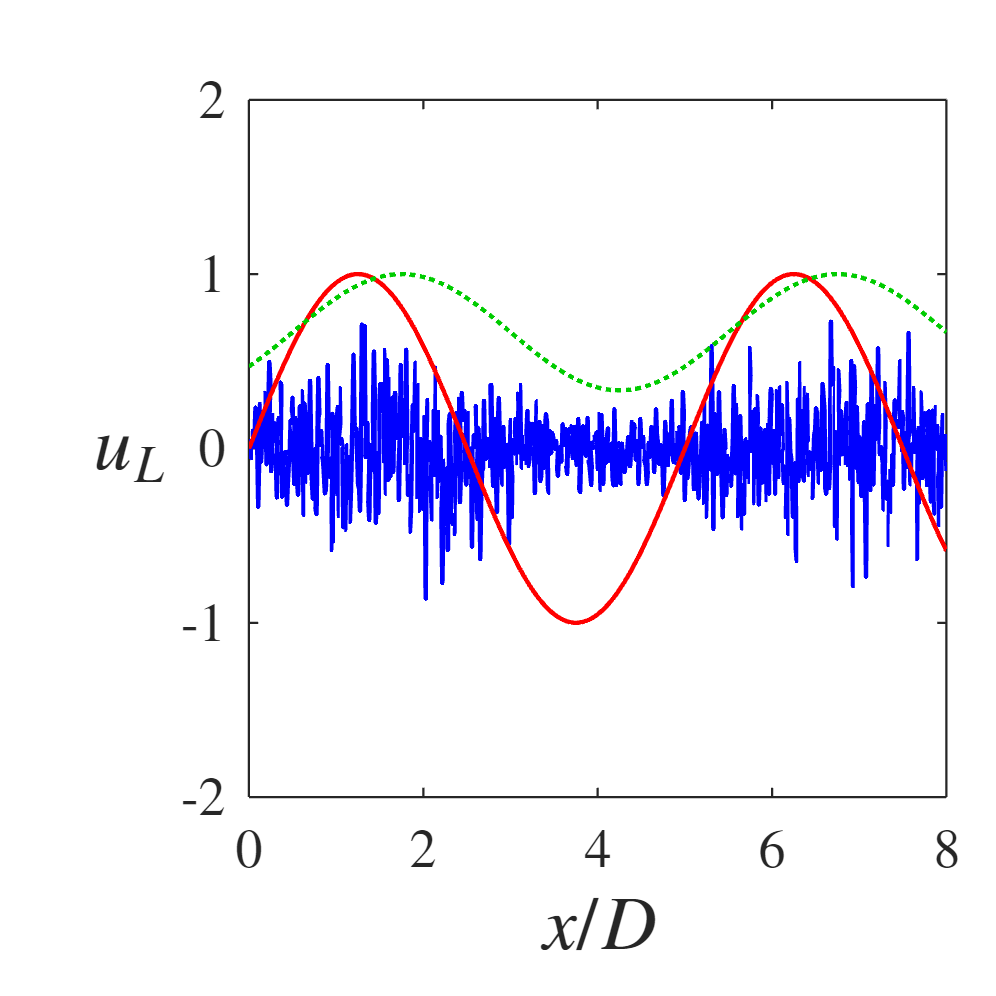

% modulated small scale signal

small_scale_amplitude = 1;
delta_xD = -0.5;
modulation_shift = 2;
amplitude_modulation = sin(k_dominant.*x+ 2*pi*delta_xD*D/lambda) + modulation_shift;
amplitude_modulation = amplitude_modulation/max(amplitude_modulation)*small_scale_amplitude;
u_S = u_S_base .* amplitude_modulation;


plot(x/D, u_S, 'Color',[0 0 1])
plot(x/D, u_L, 'Color',[1 0 0])
plot(x/D, amplitude_modulation,'Color',[0 .8 0], 'LineStyle',':')
xlim([0 x_max/D])
ylim([-2 2])
ylabel('$u_L$', 'Rotation',0)
xlabel('$x/D$')

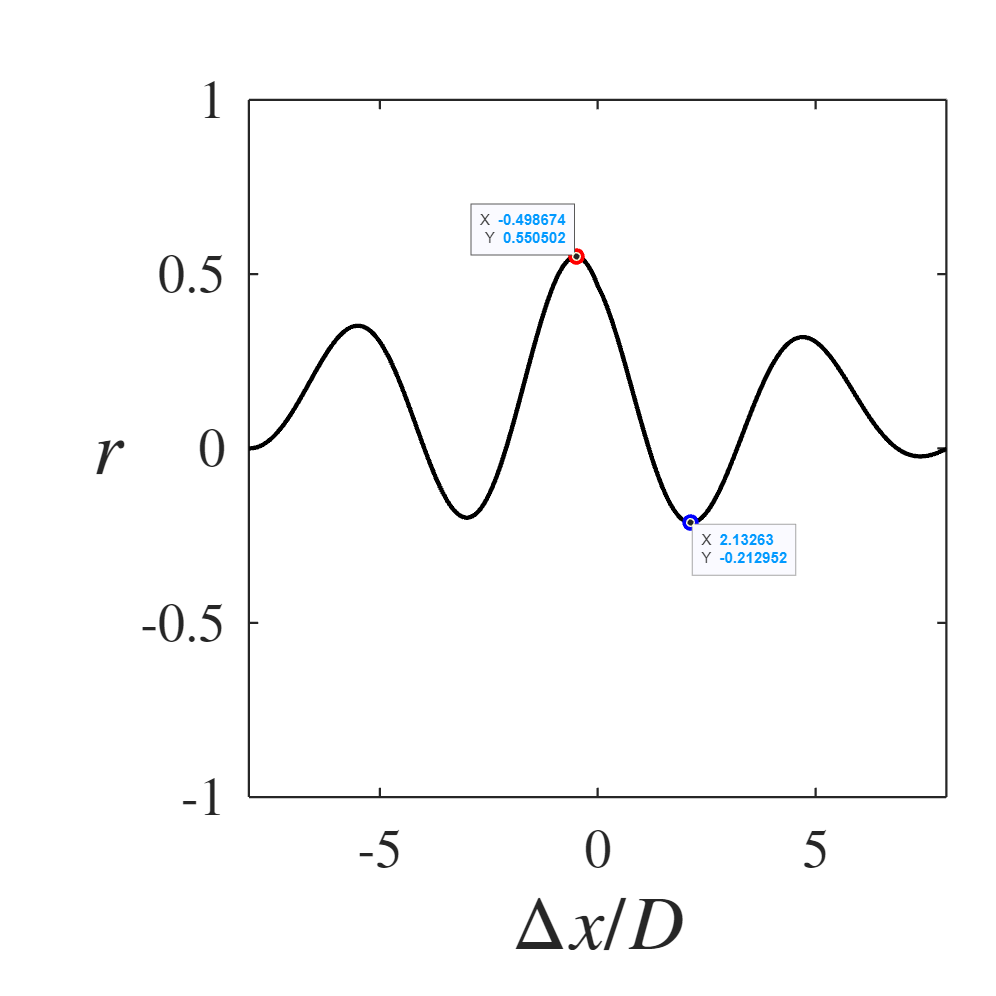


figure()
x_corr = [-fliplr(x) x(2:end)];
% r_reference = xcorr(u_L, abs(hilbert(u_S)));
r_reference = xcorr(u_L, amplitude_modulation);
r_reference = r_reference/rms(u_L)/rms(amplitude_modulation)/size(x,2);
[rmax, imax] = max(r_reference);
[rmin, imin] = min(r_reference);

plot(x_corr/D,r_reference, Color=[0 0 0])
plot(x_corr(imax)/D, rmax, Marker="o", LineStyle="none", Color=[1 0 0])
plot(x_corr(imin)/D, rmin, Marker="o", LineStyle="none", Color=[0 0 1])
xlim([x_corr(1)/D x_corr(end)/D])
ylim([-1 1])
ylabel('$r$', 'Rotation',0)
xlabel('$\Delta x/D$')

ax = gca;
chart = ax.Children(1);
datatip(chart,2.133,-0.213,"Location","southeast");
chart = ax.Children(2);
datatip(chart,-0.4987,0.5505,"Location","northwest");


u = u_L + u_S;
 


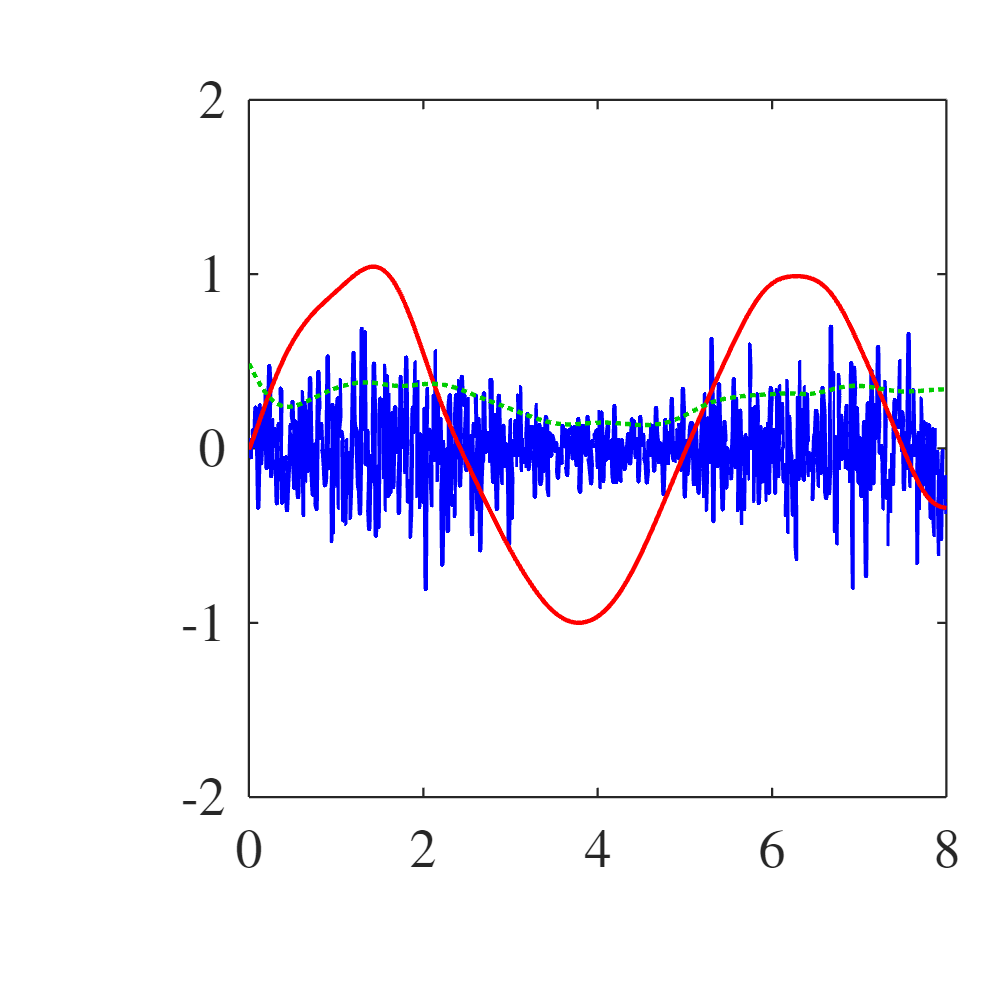


clearvars -except u x x_corr r_reference lambda amplitude_modulation D
k_n = 2*pi/(x(2) - x(1));
relative_cut_off = 5;
k_cut = 2*pi/lambda*relative_cut_off;
[b, a] = butter(3, k_cut/k_n*2); 
u_L = filtfilt(b, a, u);
u_S = u - u_L;
u_S_hilbert = abs(hilbert(u_S));
u_S_envelope = filtfilt(b, a, u_S_hilbert);
figure
plot(x/D, u_S, Color=[0 0 1])
plot(x/D, u_L, Color=[1 0 0])
plot(x/D, u_S_envelope,'Color',[0 .8 0], 'LineStyle',':')
xlim([x(1) x(end)]/D)
ylim([-1 1]*2)

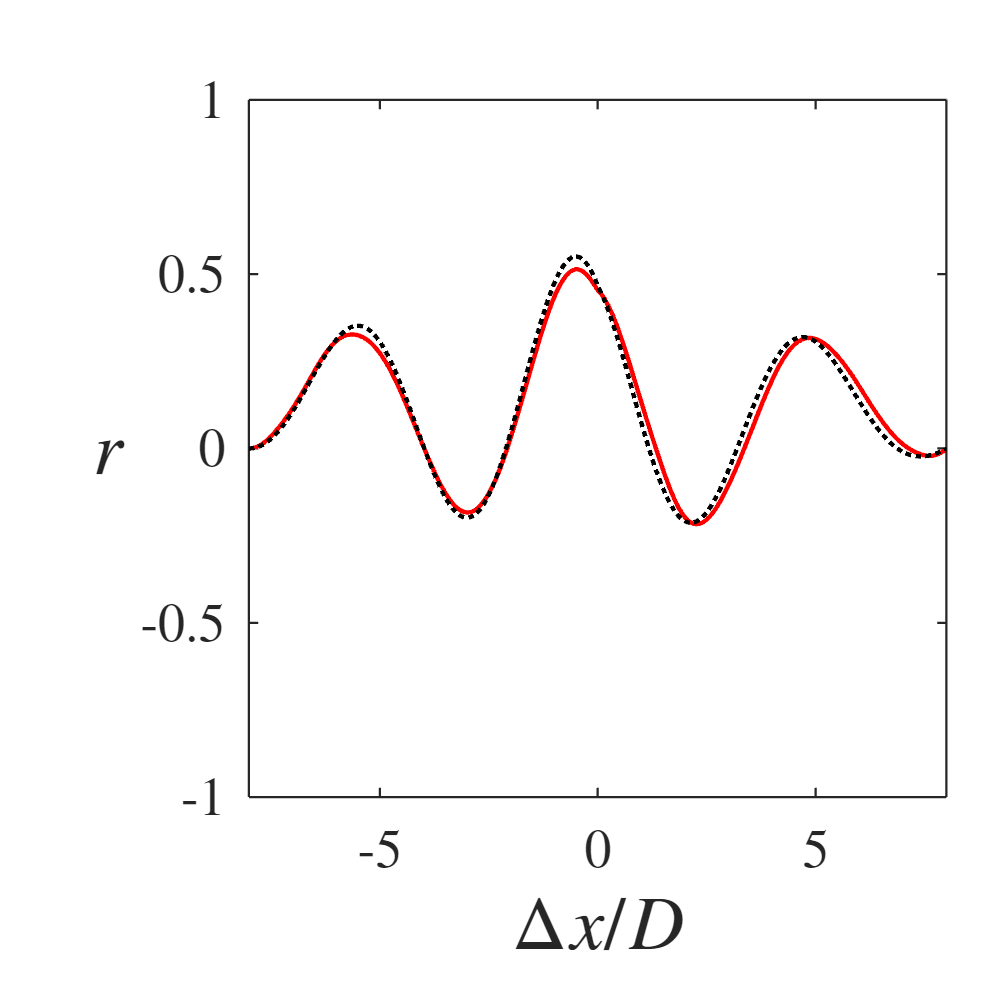


r = xcorr(u_L, u_S_envelope)/rms(u_L)/rms(u_S_envelope)/size(x,2);

figure
plot(x_corr/D, r)
plot(x_corr/D, r_reference, Color=[0 0 0], LineStyle=":")
xlim([x_corr(1)/D x_corr(end)/D])
ylim([-1 1])
ylabel('$r$', 'Rotation',0)
xlabel('$\Delta x/D$')